%B11102112 李家睿

% Clear the workspace and command window
clear
% Define the number of channels in the EEG data
channelno=34;
% Open file in read-binary mode
fileID = fopen('lab5.eeg', 'rb');
% Read the entire binary file as float32 data
eeg_data = fread(fileID, inf, 'float32');
size(eeg_data)

ans =     31884180           1


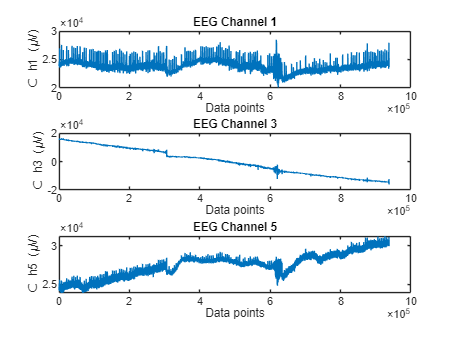

% Reshapes the data into channelno rows and multiple columns
eeg_data=reshape(eeg_data,channelno,[])';
% Close the file after reading the data
fclose(fileID);
% Plot EEG waveforms of the 1st, 3rd, and 5th channels
figure;
% Plot the data for the 1st channel
% Create the first subplot in a 3-row layout
subplot(3,1,1);
plot(eeg_data(:,1));
% Set the x-axis limits to show the first 100 samples
title('EEG Channel 1');
xlabel('Data points');
ylabel('Ｃ h1 (\muV)');
% Plot the data for the 3rd channel
% Create the second subplot in a 3-row layout
subplot(3,1,2);
plot(eeg_data(:,3));
title('EEG Channel 3');
xlabel('Data points');
ylabel('Ｃ h3 (\muV)');
% Plot the data for the 5th channel
% Create the third subplot in a 3-row layout
subplot(3,1,3);
plot(eeg_data(:,5));
title('EEG Channel 5');
xlabel('Data points');
ylabel('Ｃ h5 (\muV)')

% Select the data from channels 1, 3, and 5
selected_channels = eeg_data(:,[1, 3, 5]);
% Save the selected channels to an ASCII file
save('selected_eeg_data.txt', 'selected_channels', '-ascii');

%Today's lab is also quite interesting, we can now import data from the
%computer and process it. allowing us to plot the graph. Additionally, we
%can output ASCII to a txt file.